# `Chapter 11 - Thick walled cylinder general case`


% A and B are Lami's eqn constant
% r is general radius
% Pa and Pb are respetive internal and external pressures
% a is internal radius 
% b is outer radius

syms sigma_r sigma_theta A B r Pa Pb a b c delta v E 


## 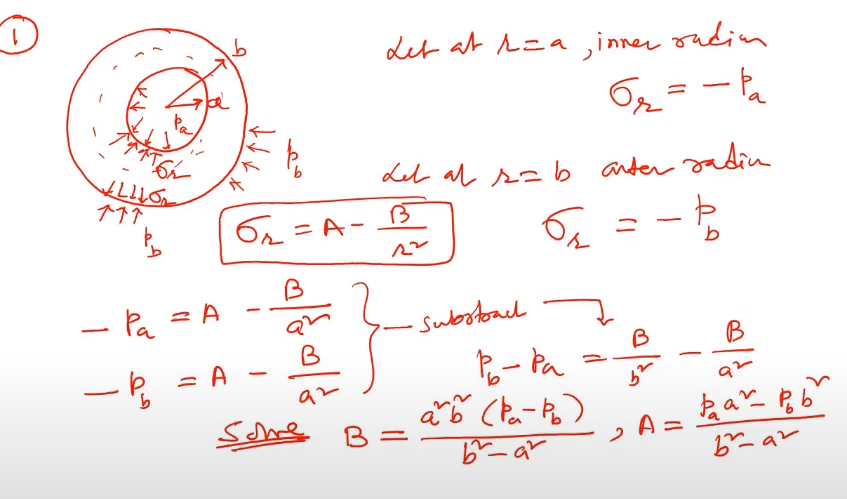

## **Here define the equations:**

eqn_r = sigma_r == A - B/r^2

$$eqn\_r = \sigma_{r}=A-\frac{B}{r^{2}}$$

eqn_theta = sigma_theta == A + B/r^2

$$eqn\_theta = \sigma_{\theta }=A+\frac{B}{r^{2}}$$

## **Solving the equations:**

eqn1 = subs(eqn_r,sigma_r,-Pa);
eqn1 = subs(eqn1,r,a)

$$eqn1 = -\mathrm{Pa}=A-\frac{B}{a^{2}}$$


eqn2 = subs(eqn_r,sigma_r,-Pb);
eqn2 = subs(eqn2,r,b)

$$eqn2 = -\mathrm{Pb}=A-\frac{B}{b^{2}}$$


[A_mat,B_mat] = equationsToMatrix([eqn1, eqn2], [A,B]);
X = linsolve(A_mat,B_mat)

$$X = \left(\begin{array}{c} -\frac{\mathrm{Pa}\,a^{2}-\mathrm{Pb}\,b^{2}}{a^{2}-b^{2}}\\ -\frac{a^{2}\,b^{2}\,\left(\mathrm{Pa}-\mathrm{Pb}\right)}{a^{2}-b^{2}} \end{array}\right)$$



eqn_r = subs(eqn_r,A,X(1));
eqn_r = subs(eqn_r,B,X(2))

$$eqn\_r = \sigma_{r}=\frac{a^{2}\,b^{2}\,\left(\mathrm{Pa}-\mathrm{Pb}\right)}{r^{2}\,\left(a^{2}-b^{2}\right)}-\frac{\mathrm{Pa}\,a^{2}-\mathrm{Pb}\,b^{2}}{a^{2}-b^{2}}$$


eqn_theta = subs(eqn_theta,A,X(1));
eqn_theta = subs(eqn_theta,B,X(2))

$$eqn\_theta = \sigma_{\theta }=-\frac{\mathrm{Pa}\,a^{2}-\mathrm{Pb}\,b^{2}}{a^{2}-b^{2}}-\frac{a^{2}\,b^{2}\,\left(\mathrm{Pa}-\mathrm{Pb}\right)}{r^{2}\,\left(a^{2}-b^{2}\right)}$$

## finding particular  value by specifying value of the parameters: 

# ( ***Always remember we need to provide radius in the formula ******not the diameters)***

 % here specify the value of parameters
Pa_value = ;
Pb_value = ;
r_value = ;
a_value = ;
b_value = ;

$$sol\_eqn\_r = \sigma_{r}=-\frac{616}{25}$$

v_value = ;

$$ans = \sigma_{r}=-24.64$$

E_value = ;

$$sol\_eqn\_theta = \sigma_{\theta }=\frac{3416}{25}$$

$$ans = \sigma_{\theta }=136.64$$

var_sub = [Pa,Pb,r,a,b]; 
var_value = [Pa_value,Pb_value,r_value,a_value,b_value];

## Substituting above defined parameters:

sol_eqn_r = subs(eqn_r,var_sub,var_value)
vpa(sol_eqn_r)
sol_eqn_theta = subs(eqn_theta,var_sub,var_value) 
vpa(sol_eqn_theta)

$$delta\_r = \frac{r\,\left(\mathrm{Pa}\,a^{2}-\mathrm{Pb}\,b^{2}\right)\,\left(v-1\right)}{\text{E}\,\left(a^{2}-b^{2}\right)}-\frac{a^{2}\,b^{2}\,\left(\mathrm{Pa}-\mathrm{Pb}\right)\,\left(v+1\right)}{\text{E}\,r\,\left(a^{2}-b^{2}\right)}$$

## Finding the change in radius of thick cylinderical shell:

% var_sub2 = [v E];
% var_sub2_value = [v E]; % here define the values of poisson ratio and E
% 
% delta_r = ((1-v)/E)*X(1)*r + ((1+v)/E)*X(2)/r

$$Ps = \frac{\text{E}\,\delta \,\left(a^{2}-c^{2}\right)\,\left(b^{2}-c^{2}\right)}{2\,c^{3}\,\left(a^{2}-b^{2}\right)}$$

% sol_delta_r = subs(delta_r,var_sub,var_value);
% sol_delta_r = subs(sol_delta_r,var_sub2,var_sub2_value);